%% Parametros de las superficies

%clear all
close all
clc
% Radios de curvatura
Radio1=20;
Radio2=-20;
MR=[Radio1, Radio2]; 
% constante de conicidad
MK=[0,0];
% posicion de los vertices 
% o mejor dicho "ancho de la lente"
AnchoLente=10;
MT=[0, AnchoLente]; 
%  Indices de refraccion 
IndiceExterior=1;
IndiceLente=1.52;
INDICES=[IndiceExterior, IndiceLente, IndiceExterior];        
%% Posición del objeto o fuentes
y0=linspace(-11,11,17);
x0=-30*ones(size(y0));
%% rayos incidentes 
Ix=ones(size(x0));
Iy=0*Ix;




%% Calculo de la interseccion y de la refraccion 
figure('units','normalized','outerposition',[0 0 1 1]);
H=12;   
r1=MR(1); k1=MK(1); Q1=k1+1;  t1=MT(1);
r2=MR(2); k2=MK(2); Q2=k2+1;  t2=MT(2);
[Xs,Ys]=LENTE(H, Q1,r1,t1,Q2,r2,t2);
pgon = polyshape(Xs,Ys);
plot(pgon,'FaceColor','cyan','FaceAlpha',0.1)
hold on

C = {'.g','.r','.b'};
for i=1:2
    r1=MR(i); k1=MK(i); t1=MT(i);  n1=INDICES(i); n2=INDICES(i+1);
  %%% interseca al rayo incidente con la interfase curva  
 [x1,y1, Xi]=INTERSECA(x0, y0, Ix, Iy, r1,k1,t1);

 quiver(x0,y0,Xi.*Ix, Xi.*Iy,0,C{i}, 'Linewidth',1.3);
 hold on 
 plot(x1,y1,'*k','Linewidth',1.2, 'Markersize',6)
 hold on 
 %%% refracta al rayo incidente 
 [Tx,Ty]=REFRACTA(x1, y1, Ix, Iy,k1,r1,t1,n1,n2 ); 
 Ix=Tx; Iy=Ty;
 x0=x1; y0=y1;
end
  quiver(x0,y0,45.*Ix, 45.*Iy,0,'.b', 'Linewidth',1.3);
  hold on
  
%   L=-y0./Ty;
%   quiver(x0,y0,L.*Tx, L.*Ty,0,'--.b', 'Linewidth',1.5);
%   hold on
  
n1=INDICES(1); n2=INDICES(2); n3=INDICES(3);
Fobjeto=(n1/(n2-n1))*( (1/MR(1))-(1/MR(2)))^(-1)

Fobjeto = 20

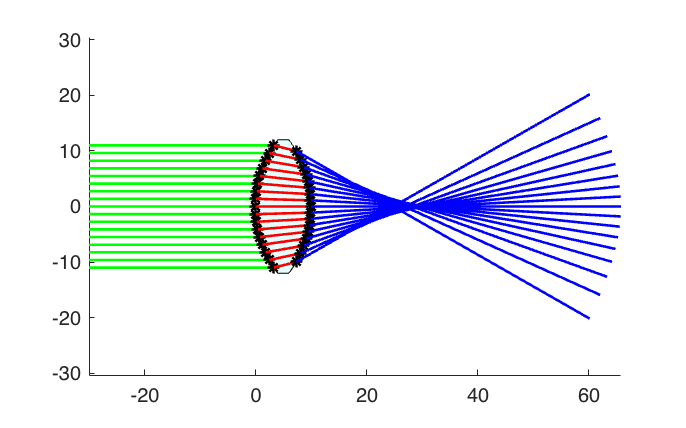

  
  

  axis equal